依赖[统一实验分析作图v20.2.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/)

声水初始、学会和迁移到光水的热图

MOpBaseline=TransferLearning.MOpBaseline;

GroupNtats=UniExp.NtatsCellStrip(MOpBaseline.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath("查询表.xlsx"),'Fig1GI'),UniExp.Flags.ZScore,1:24,UniExp.Flags.Median));

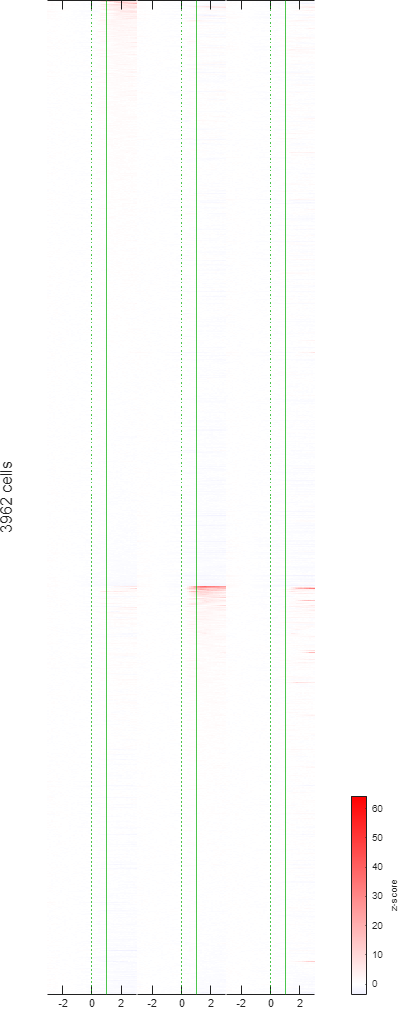

Fig=figure;
[Layout,Axes]=UniExp.LanearHeatmap(UniExp.HeatmapSort(GroupNtats,["Naive","Learned"]).NTATS{:,:,["Naive","Learned","Transfer"]},XData=[-3,3],LMHColor=[0,0,1;1,1,1;1,0,0],Flags=[UniExp.Flags.HideYAxis,UniExp.Flags.SymmetricColormap],Layout=tiledlayout(5,4,TileSpacing='none',Padding='tight'));
CB=colorbar;
CB.Layout.Tile=20;
CB.Label.String='z-score';
for A=1:3
	xline(Axes(A),0,':',Color=[0,0.681,0]);
	xline(Axes(A),1,'-',Color=[0,0.681,0]);
	Axes(A).TickDir='in';
	Axes(A).Layout.TileSpan=[5,1];
	box(Axes(A),'on');
end
ylabel(Layout,sprintf('%u cells',height(GroupNtats)));
MATLAB.Graphics.FigureAspectRatio(2,5,MATLAB.Flags.Amplify);
print(Fig,TransferLearning.ProjectPath('Fig1G.svg'),'-dsvg');